clear
syms u(t) v(t)

k = 16;
m = 1;
a = 0;
b = 8;
u0 = 9;
v0 = 0;
n = 100;

f=@(t,u,v) v

f = function_handle with value:
    @(t,u,v)v


g=@(t,u,v) -k/m*u

g = function_handle with value:
    @(t,u,v)-k/m*u



sedo = [diff(u,t)==f(t,u,v), diff(v,t)==g(t,u,v)]

$$sedo(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}u\left(t\right)=v\left(t\right) & \frac{\partial }{\partial t}v\left(t\right)=-16\,u\left(t\right) \end{array}\right)$$

ci = [u(a)==u0, v(a)==v0]

$$ci = \left(\begin{array}{cc} u\left(0\right)=9 & v\left(0\right)=0 \end{array}\right)$$

[uExata,vExata]= dsolve(sedo,ci)

$$uExata = 9\,\cos\left(4\,t\right)$$

$$vExata = -36\,\sin\left(4\,t\right)$$

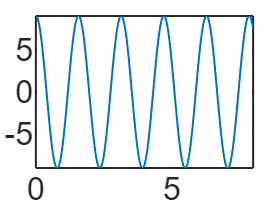


fplot(uExata,[a,b])



%whos